# DATA 5: MOVING MINST

% (C) 2026 Moo K. Chung
% University of Wisconsin
%
% DESCRIPTION
% This dataset contains a compact MATLAB version of the Moving MNIST video
% benchmark. Each sample is a short grayscale video sequence showing one or
% two handwritten MNIST digits undergoing smooth translational motion on a
% 2D grid. The data are intended for studying time-varying image structure,
% motion, geometry, and topology.
%
% SOURCE
% The original Moving MNIST dataset was introduced in:
%
%   Srivastava, N., Mansimov, E., & Salakhudinov, R. (2015).
%   Unsupervised learning of video representations using LSTMs.
%   Proceedings of the 32nd International Conference on Machine Learning (ICML).
%   PMLR, Vol. 37, pp. 843–852.
%
% @inproceedings{srivastava2015unsupervised,
%   title={Unsupervised learning of video representations using lstms},
%   author={Srivastava, Nitish and Mansimov, Elman and Salakhudinov, Ruslan},
%   booktitle={International conference on machine learning},
%   pages={843--852},
%   year={2015},
%   organization={PMLR}
% }
% https://proceedings.mlr.press/v37/srivastava15.pdf
%
% If you are using data here, please reference this paper. 


% DATA FORMAT
% The variable X is a 4D uint8 array of size:
%
%   X : [64 x 64 x 20 x 1000]
%
% where:
%   - 64 x 64   : spatial resolution (image height x width)
%   - 20        : number of time frames per sequence
%   - 1000      : number of video sequences
%
% Each entry X(:,:,t,n) is a single grayscale image frame at time t from
% sequence n, with intensity values in [0,255].

load moving_mnist_1000

size(X)

ans =           64          64          20        1000


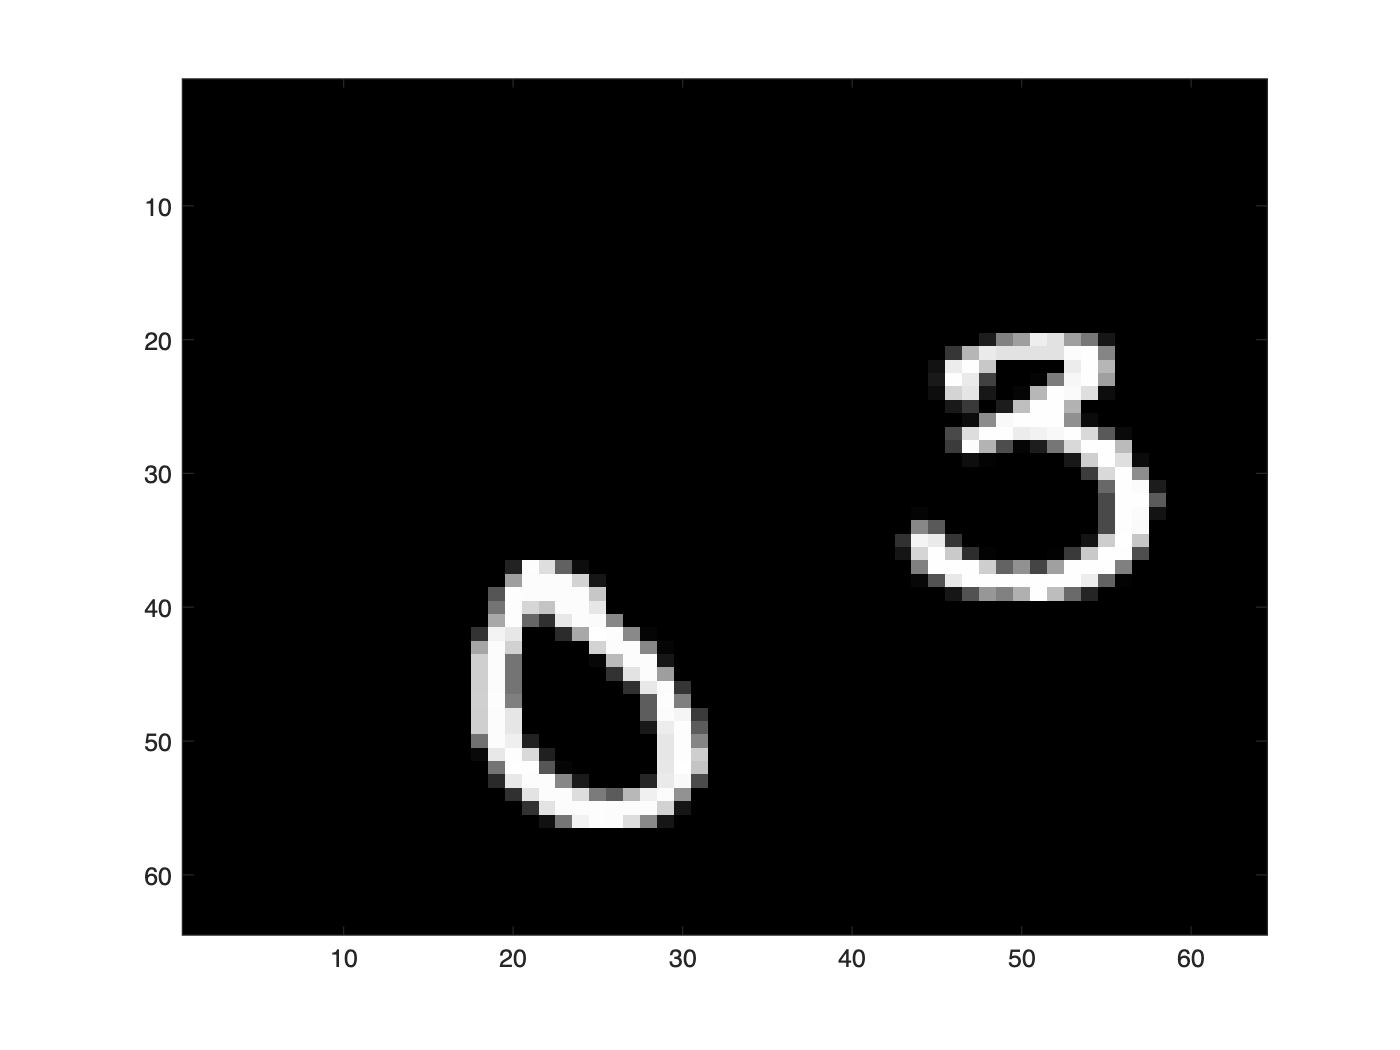


figure; imagesc(X(:,:,10,1));  colormap gray; %10th frame in the first animation

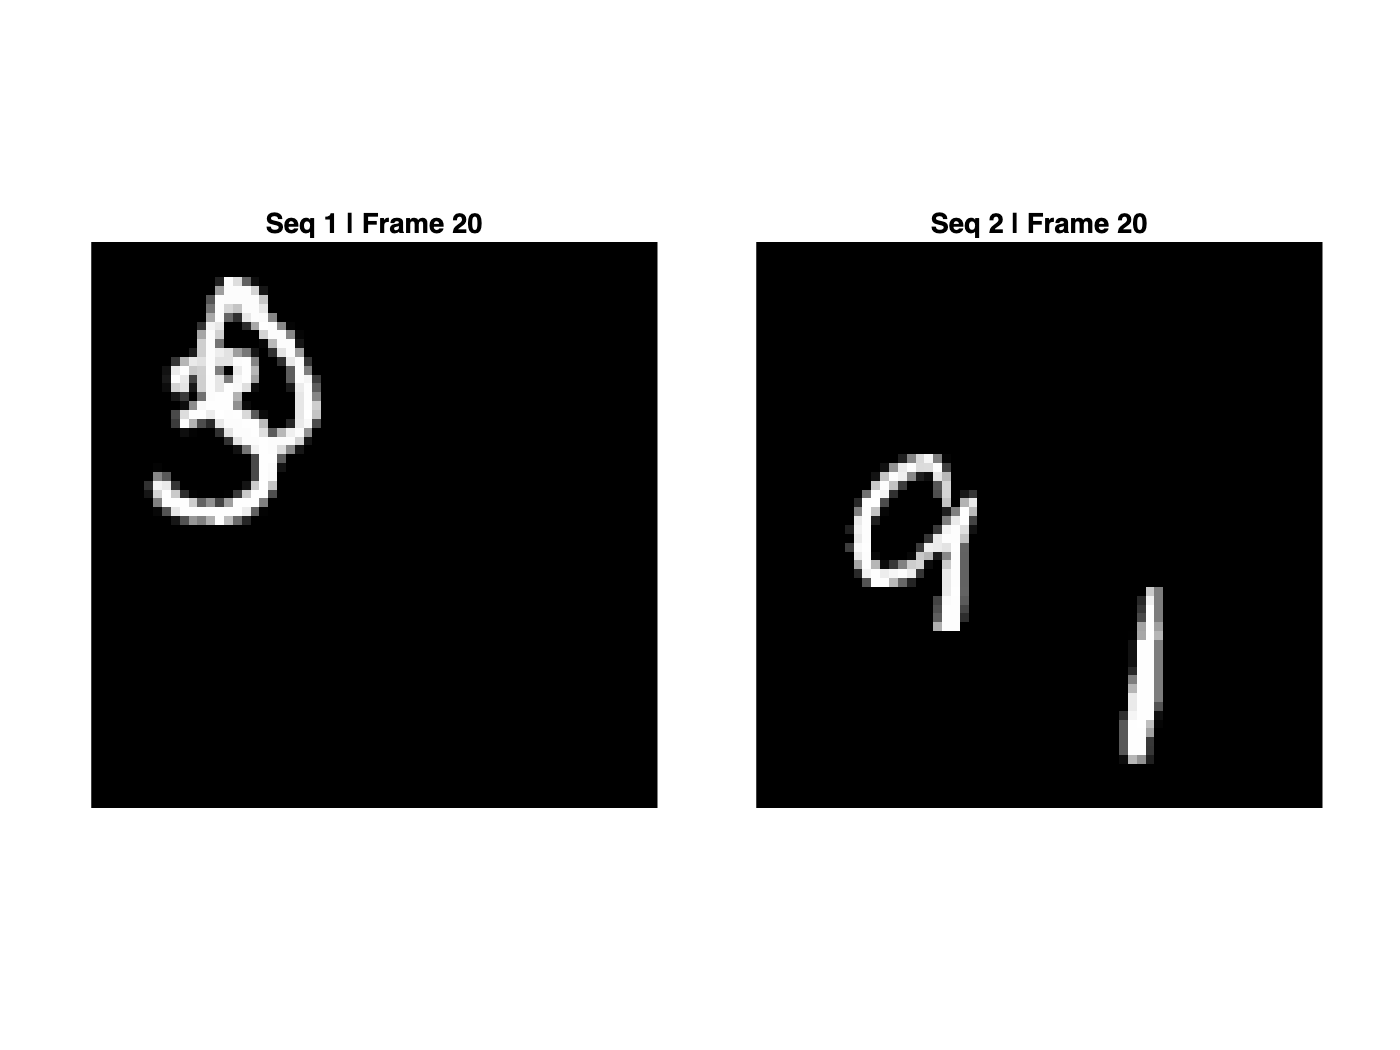

n1 = 1;        % first sequence
n2 = 2;        % second sequence

figure;
tiledlayout(1,2,'Padding','compact','TileSpacing','compact');

for t = 1:size(X,3)
    nexttile(1);
    imagesc(X(:,:,t,n1));
    colormap gray;
    axis image off;
    title(sprintf('Seq %d | Frame %d', n1, t));

    nexttile(2);
    imagesc(X(:,:,t,n2));
    colormap gray;
    axis image off;
    title(sprintf('Seq %d | Frame %d', n2, t));

    drawnow;
end

## PROJECT 9 Topological clustering of dynamic data

% The project is specific to this dataset. 
%
% Goal.
% The goal of this project is to introduce students to topological representations 
% and distances for high-dimensional image data and time-varying image sequences. 
% Using the Moving MNIST dataset, students will develop principled methods to discretize 
% images as cubical complexes, construct MONOTONE graph filtrations, and design topology-aware 
% distances that capture geometric and structural differences beyond pixelwise similarity. 
% The project emphasizes understanding how topology evolves under filtration and time, and 
% how such information can be leveraged for clustering static images and dynamic animations.
%
% Description.
% In the first part of the project, students treat each image frame independently, resulting 
% in a collection of 20,000 static grayscale images. Each image is discretized as a cubical 
% complex induced by the pixel grid, and a monotone filtration is constructed by thresholding 
% image intensities so that topological invariants, specifically Betti-0 and Betti-1, evolve 
% monotonically along the filtration. Students compute topological summaries derived from these 
% filtrations and use them to design an effective topological distance between image frames. 
% This distance is then used to cluster the 20,000 frames, revealing structure that reflects 
% shape and connectivity rather than raw intensity differences. 
% 
% In the second part of the project, students extend these ideas to time-varying 
% data. They design a topology-based distance between animations by aggregating or comparing 
% the evolution of topological summaries over time, and use this distance to cluster the 1,000 
% video sequences. This highlights how temporal coherence and motion influence topological structure 
% in dynamic data.
%
%Learning Outcomes.
% By completing this project, students will gain a concrete understanding of how images can be modeled 
% as cubical complexes and how filtrations encode geometric and topological information. They will learn 
% how Betti numbers reflect meaningful structural features such as connected components and holes, and 
% how these features change under intensity-based filtrations and over time. Students will develop the 
% ability to design topology-aware distances for both static and dynamic data and to apply these distances 
% to unsupervised learning tasks such as clustering. More broadly, the project builds intuition for why 
% topological methods are robust to noise and deformation, and how topology provides a complementary 
% perspective to traditional pixel-based or statistical approaches for analyzing complex, time-varying data.




